# Distributed model of power - Multiple nanogrids within microgrid   

Creating a single agent controller design which can connect any type of load, source or another agent controller. Creat a robust, distributed control system for ac microgrid  

clc
clear all
close all

#### Settings

s = settings;
s.matlab.colors.programmingtools.AutomaticallyHighlightVariables.TemporaryValue = 1;
s.matlab.colors.programmingtools.VariableHighlightColor.TemporaryValue = [25 200 25];

## List down all the components connected to Nano grid Controller 

List all the observations / states / inputs  

The controller can be connected to the

- Solar cell 

- Wind

- battery

- grid controller

- load

Create the observation specifications or state for solar cell PV1. The PV1 observations contain the power profile or product forecast specification. 

% power_profile = [1 2 3 44 556 78 9];  % as an example
% PV_power_obsInfo = rlNumericSpec(size(power_profile));
t  = [0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19, 20, 21, 22, 23];
PV = [0, 0, 0, 0, 0, 0, 0, 0.1, 0.3, 0.5, 0.6, 0.7, 0.8, 0.9, 1, 0.8, 0.6, 0.4, 0.2, 0, 0, 0, 0, 0];
PV = [0, 0, 0, 0, 0, 0, 12.5, 25, 37.5, 50, 62.5, 75, 87.5, 100, 87.5, 75, 62.5, 50, 37.5, 25, 12.5, 0, 0, 0];
k = 1000;

% <------------------------------- Sources -------------------------------> 
% PV
PV_power_rating = 100*k;
PV_power_state = 1;
PV_power_state_lower_limit = 0;
PV_power_state_upper_limit = PV_power_rating;

% PV_power_current_capacity_state = 1;
% PV_power_current_capacity_state_lower_limit = PV_power_state_lower_limit;
% PV_power_current_capacity_state_upper_limit = PV_power_state_upper_limit;

PV_power_forecast_state = 1;
PV_power_forecast_state_lower_limit = PV_power_state_lower_limit;
PV_power_forecast_state_upper_limit = PV_power_state_upper_limit;

PV_state = [PV_power_state; ];
PV_state_lower_limit = [PV_power_state_lower_limit];
PV_state_upper_limit = [PV_power_state_upper_limit];


% Wind
Wind_power_rating = 100*k;
Wind_power_state = 1;
Wind_power_state_lower_limit = 0;
Wind_power_state_upper_limit = Wind_power_rating;

% Wind_power_current_capacity_state = 1;
% Wind_power_current_capacity_state_lower_limit = Wind_power_state_lower_limit;
% Wind_power_current_capacity_state_upper_limit = Wind_power_state_upper_limit;

Wind_power_forecast_state = 1;
Wind_power_forecast_state_lower_limit = Wind_power_state_lower_limit;
Wind_power_forecast_state_upper_limit = Wind_power_state_upper_limit;

Wind_state = [Wind_power_state];
Wind_state_lower_limit = [Wind_power_state_lower_limit];
Wind_state_upper_limit = [Wind_power_state_upper_limit];


% Sources
Sources_state              = [PV_state; Wind_state];
Sources_state_lower_limits = [PV_state_lower_limit; Wind_state_lower_limit];
Sources_state_upper_limits = [PV_state_upper_limit; Wind_state_upper_limit];


% <------------------------------- Battery ------------------------------> 
battery_capacity_rating = 10*k;   % 10kWh
battery_capacity_state = 1;
battery_capacity_state_lower_limit = 0;
battery_capacity_state_upper_limit = battery_capacity_rating;
battery_initial_capacity = 0.5*battery_capacity_state_upper_limit;

battery_SOC_state = 1;
battery_SOC_state_lower_limit = 0;
battery_SOC_state_upper_limit = 1;

% capacity = 10kWh, battery can gave 10 kW for 1 hour as safe limit
battery_power_rating = battery_capacity_rating;   
battery_charge_power_state = 1;
battery_charge_power_state_lower_limit = 0;
battery_charge_power_state_upper_limit = battery_power_rating;

battery_discharge_power_state = 1;
battery_discharge_power_state_lower_limit = 0;
battery_discharge_power_state_upper_limit = battery_power_rating;

% Battery
BESS_state =              [battery_capacity_state; battery_SOC_state; battery_charge_power_state; battery_discharge_power_state];
BESS_state_lower_limits = [battery_capacity_state_lower_limit; battery_SOC_state_lower_limit; battery_charge_power_state_lower_limit; battery_discharge_power_state_lower_limit];
BESS_state_upper_limits = [battery_capacity_state_upper_limit; battery_SOC_state_upper_limit; battery_charge_power_state_upper_limit; battery_discharge_power_state_upper_limit];

% <--------------------------- Nano Grid Controller --------------------------> 
nano_grid_controller_power_rating = 50*k;    % assume controllers can share power without bound
nano_grid_controller_power_state = 1;
nano_grid_controller_power_state_lower_limit = 0;
nano_grid_controller_power_state_upper_limit = nano_grid_controller_power_rating;

% <--------------------------- Micro Grid Controller -------------------------> 
micro_grid_controller_power_rating = 1000*k;    % assume microgrid can share power without bound
micro_grid_controller_power_state = 1;
micro_grid_controller_power_state_lower_limit = 0;
micro_grid_controller_power_state_upper_limit = micro_grid_controller_power_rating;

% <----------------------------------- Loads ---------------------------------> 
% residential or commercial load
static_load_rating = 50*k;    % 50 kW load
static_load_state = 1;   
static_load_state_lower_limit = 0;
static_load_state_upper_limit = static_load_rating;
static_load_priority_factor = 1;   % 100%
ksl_min = static_load_priority_factor;


% thermostatic load 
TCL_load_rating = 50*k;        % 50 kW load
TCL_load_state = 1;      
TCL_load_state_lower_limit = 0;
TCL_load_state_upper_limit = TCL_load_rating;
TCL_load_priority_factor = 0.5;   % 50% - 100%
ktcl_min = TCL_load_priority_factor;


% EV charging Station
EV_load_rating = 50*k;         % 50 kW load
EV_load_state = 1;       
EV_load_state_lower_limit = 0;
EV_load_state_upper_limit = EV_load_rating;
EV_load_priority_factor = 0.5;   % 20% - 100%
kev_min = EV_load_priority_factor;

% Loads
Loads_state =              [static_load_state;             TCL_load_state;              EV_load_state];
Loads_state_lower_limits = [static_load_state_lower_limit; TCL_load_state_lower_limit;  EV_load_state_lower_limit];
Loads_state_upper_limits = [static_load_state_upper_limit; TCL_load_state_upper_limit;  EV_load_state_upper_limit];

% Total power threshold
sum_power_threshold_upper_limit = 10;     % +10 W
sum_power_threshold_lower_limit = -10;    % -10 W
 
% <-------------------- Observations / States / Inputs -------------------> 
% List Down all the the states
states_or_obs = [Sources_state; Loads_state];
number_of_states_or_obs = size(states_or_obs , 1);

## Create Observation for Nano grid Controller Agent 1

The controller can be connected to the

- Solar cell 

- Wind

- battery

- load

- grid controller

Create the observation specifications or state for all the components. 

Observation_Information = rlNumericSpec([number_of_states_or_obs 1]); 
Observation_Information.Name = 'All the Sources, energy storages, controllers and loads';
Observation_Information.Description = 'PV, Wind, Battery, Grid, Load';
Observation_Information.LowerLimit = [Sources_state_lower_limits; Loads_state_lower_limits];
Observation_Information.UpperLimit = [Sources_state_upper_limits; Loads_state_upper_limits];

## Create Action for Nano grid Controller Agent 1

The controller can take the following actions

- Battery action a_B

- Grid Action a_g

- TCL Load Action a_tcl

- Static Load Action a_st

- Electric Vehicle Load Action a_ev

Create the Action specifications for nano grid Controller 

% <------------------------------- Sources Action -------------------------------> 
PV_power_action = 1;
PV_power_action_lower_limit = 0;
PV_power_action_upper_limit = PV_power_rating;

Wind_power_action = 1;
Wind_power_action_lower_limit = 0;
Wind_power_action_upper_limit = Wind_power_rating;

% Sources
Sources_action             = [PV_power_action; Wind_power_action];
Sources_action_lower_limit = [PV_power_action_lower_limit; Wind_power_action_lower_limit];
Sources_action_upper_limit = [PV_power_action_upper_limit; Wind_power_action_upper_limit];


% <------------------------------- Battery Action -------------------------------> 
BESS_charging_action_rating = battery_power_rating;
BESS_charging_action = 1;
BESS_charging_action_lower_limit = 0;
BESS_charging_action_upper_limit = BESS_charging_action_rating;

BESS_discharging_action_rating = battery_power_rating;
BESS_discharging_action = 1;
BESS_discharging_action_lower_limit = 0;
BESS_discharging_action_upper_limit = BESS_discharging_action_rating;

BESS_action = [BESS_charging_action];                          % ; BESS_discharging_action]
BESS_action_lower_limit = [BESS_charging_action_lower_limit];  % ; BESS_discharging_action_lower_limit]
BESS_action_upper_limit = [BESS_charging_action_upper_limit];  % ; BESS_discharging_action_upper_limit]

% <------------------------- Nano Grid Controller Action -------------------------> 
nano_grid_controller_action = 1;
nano_grid_controller_action_lower_limit = 0;
nano_grid_controller_action_upper_limit = nano_grid_controller_power_rating;

% <------------------------- Micro Grid Controller Action -------------------------> 
micro_grid_controller_action = 1;
micro_grid_controller_action_lower_limit = 0;
micro_grid_controller_action_upper_limit = micro_grid_controller_power_rating;

% <--------------------------------- Loads Action --------------------------------> 
% residential or commercial load
static_load_action = 1;   
static_load_action_lower_limit = 0;
static_load_action_upper_limit = static_load_rating;

% thermostatic load 
TCL_load_action = 1;      
TCL_load_action_lower_limit = 0;
TCL_load_action_upper_limit = TCL_load_rating;

% EV charging Station
EV_load_action = 1;       
EV_load_action_lower_limit = 0;
EV_load_action_upper_limit = EV_load_rating;

% Loads
Loads_action =              [static_load_action;             TCL_load_action;              EV_load_action];
Loads_action_lower_limits = [static_load_action_lower_limit; TCL_load_action_lower_limit;  EV_load_action_lower_limit];
Loads_action_upper_limits = [static_load_action_upper_limit; TCL_load_action_upper_limit;  EV_load_action_upper_limit];

% <----------------------------------- Actions -----------------------------------> 
% List Down all the the actions
actions = [Sources_action; Loads_action];
number_of_actions = size(actions , 1);

#### Action Informations

Action_Information = rlNumericSpec([number_of_actions 1]); 
Action_Information.Name = 'Battery, Nano Grid and Load Actions';
Action_Information.Description = 'Contain battery, Connected nano grid and load actions';
Action_Information.LowerLimit = [Sources_action_lower_limit; Loads_action_lower_limits];
Action_Information.UpperLimit = [Sources_action_upper_limit; Loads_action_upper_limits];

## Create Environment

Create a Simulink environment interface, specifying the block paths for both agent blocks. The order of the block paths must match the order of the observation and action specification cell arrays.

The training goal is to make the ego car travel at a set velocity while maintaining a safe distance from lead car by controlling longitudinal acceleration and braking, while also keeping the ego car travelling along the centerline of its lane by controlling the front steering angle. 

Open the model.

system_model = "zzzzzzzzLPDs_single_agent_tech";
controller1_location = "/Nano_Grid_Controller1";
agent1 = "/RL Agent1";
agent1_location = system_model + controller1_location + agent1;  

controller2_location = "/Nano_Grid_Controller2";
agent2 = "/RL Agent2";
agent2_location = system_model + controller2_location + agent2;  
% agents_loc =  system_model + ["/RL Agent1", "/RL Agent2"];
agents_location = agent1_location;   

Create a Simulink environment interface

%environment = rlSimulinkEnv(system_model, agents_location, Observation_Information, Action_Information)
%open_system(system_model)

## Reset Environment 

Specify a reset function for the environment. The reset function `resetMap` ensures that the robots start from random initial positions at the beginning of each episode. The random initialization makes the agents robust to different starting positions and improves training convergence.

environment.ResetFcn = @(in)localResetFcn(in, system_model,...
    PV_power_rating, ...
    Wind_power_rating, ...
    battery_power_rating, ...
    nano_grid_controller_power_rating, ...
    micro_grid_controller_power_rating, ...
    static_load_rating, ...
    TCL_load_rating, ...
    EV_load_rating);

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds.

Ts = 0.05;
Tf = 24;

Fix the random generator seed for reproducibility.

rng(0)

## Create the Critic

DDPG (deep deterministic policy gradient) agents use a parametrized Q-value function approximator to estimate the value of the policy. A Q-value function critic takes the current observation and an action as inputs and returns a single scalar as output (the estimated discounted cumulative long-term reward for which receives the action from the state corresponding to the current observation, and following the policy thereafter).

To model the parametrized Q-value function within the critic, use a neural network with two input layers (one for the observation channel, as specified by `obsInfo`, and the other for the action channel, as specified by `actInfo`) and one output layer (which returns the scalar value).

Define each network path as an array of layer objects. Assign names to the input and output layers of each path. These names allow you to connect the paths and then later explicitly associate the network input and output layers with the appropriate environment channel. Obtain the dimension of the observation and action spaces from the `obsInfo` and `actInfo` specifications. 

% Observation path
observation_Path = [
    featureInputLayer(Observation_Information.Dimension(1),Name="Observation Information Input layer 1")
    fullyConnectedLayer(50 , Name = "Observation Fully Connected layer 2")
    reluLayer(  Name = "Observation Rectified Linear Unit (ReLU) layer 3")
    fullyConnectedLayer(25 , Name = "Observation Fully Connected layer 4")
    ];

% Action path
action_Path = [
    featureInputLayer(Action_Information.Dimension(1) , Name = "Action Information layer 1")
    fullyConnectedLayer(50 , Name = "Action Fully Connected layer 2")
    reluLayer(  Name = "Action Rectified Linear Unit (ReLU) layer 3")
    fullyConnectedLayer(25 , Name = "Action Information layer 4")
    ];

% Common path
common_Path = [
    additionLayer(2,Name="Common Path addition layer 1")
    reluLayer(Name = "Common Path Rectified Linear Unit (ReLU) layer 2")
    fullyConnectedLayer(1,Name="QValue layer 3")
    ];

% Create layergraph, add layers and connect them
critic_Network = layerGraph();
% add all of the layers 
critic_Network = addLayers(critic_Network , observation_Path);
critic_Network = addLayers(critic_Network , action_Path);
critic_Network = addLayers(critic_Network , common_Path);
% connect layers
critic_Network = connectLayers(critic_Network,"Observation Fully Connected layer 4"   ,"Common Path addition layer 1/in1");
critic_Network = connectLayers(critic_Network,"Action Information layer 4","Common Path addition layer 1/in2");
% network layers to an initialized dlnetwork object representing a deep neural network
critic_Network = dlnetwork(critic_Network);
summary(critic_Network);

   Initialized: true

   Number of learnables: 3.1k

   Inputs:
      1   'Observation Information Input layer 1'   5 features
      2   'Action Information layer 1'              5 features



Plots of all layers

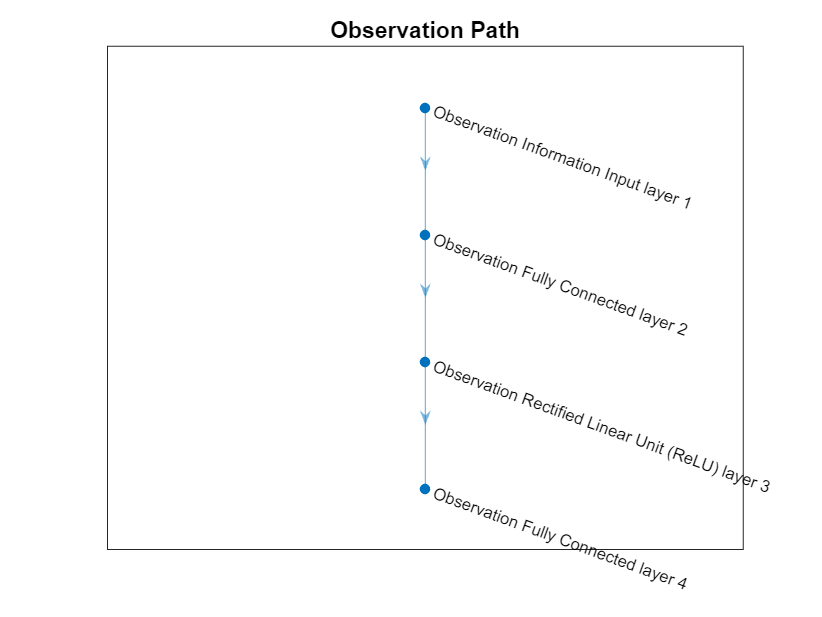

obs = layerGraph(observation_Path);
act = layerGraph(action_Path);
com = layerGraph(common_Path);

figure(1)
plot(obs);
title("Observation Path")

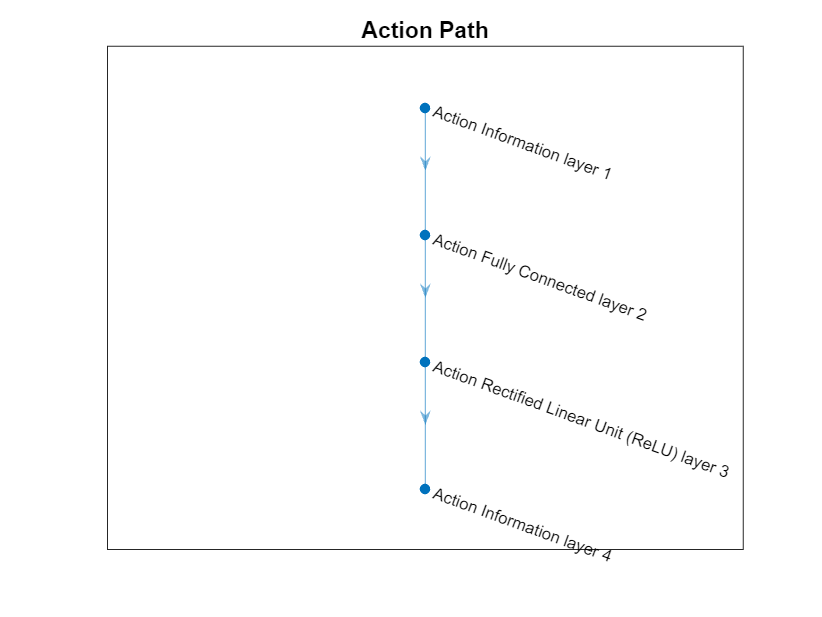


figure(2)
plot(act);
title("Action Path")

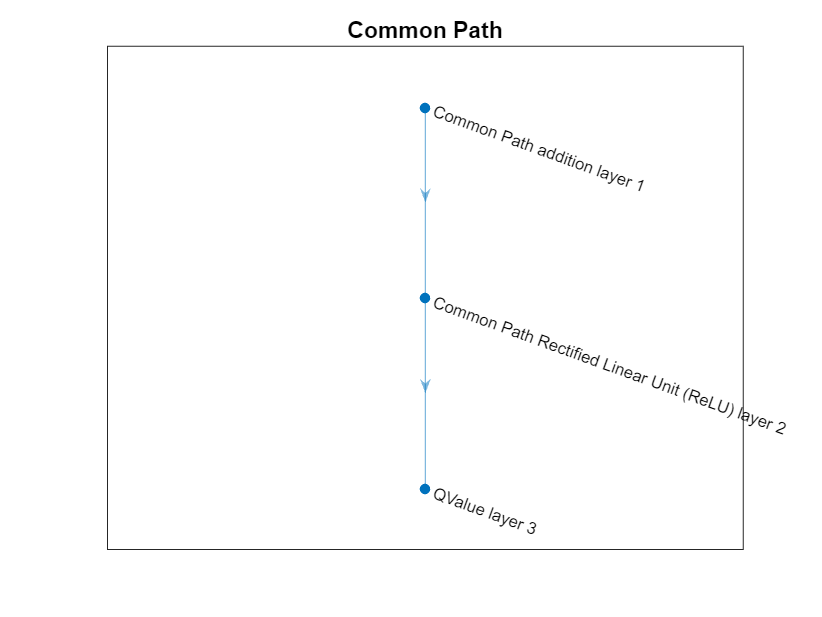


figure(3)
plot(com);
title("Common Path")

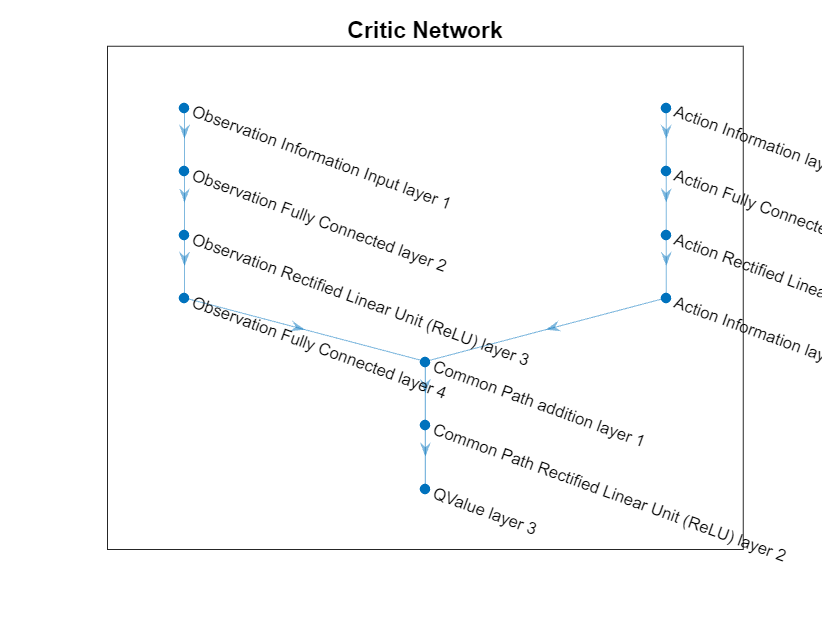


figure(4)
plot(critic_Network)
title("Critic Network")

Create the critic approximator object using `criticNet`, the environment observation and action specifications, and the names of the network input layers to be connected with the environment observation and action channels. For more information, see [`rlQValueFunction`](docid:rl_ref#mw_e6e7abac-0a33-423b-8473-1409879db701). Evaluate the following link: [Create Policies and Value Functions](https://www.mathworks.com/help/reinforcement-learning/ug/create-policy-and-value-functions.html)

critic = rlQValueFunction(critic_Network, Observation_Information ,Action_Information, ObservationInputNames = "Observation Information Input layer 1",  ActionInputNames = "Action Information layer 1");

To check your critic, use the `getValue` function to return the value of a random observation and action, given the current network weights.

v = getValue(critic,{rand(Observation_Information.Dimension)},{rand(Action_Information.Dimension)})

v = single
-0.4545

## Create the Actor

DDPG agents use a parametrized deterministic policy over continuous action spaces, which is learned by a continuous deterministic actor.

A continuous deterministic actor implements a parametrized deterministic policy for a continuous action space. This actor takes the current observation as input and returns as output an action that is a deterministic function of the observation. 

To model the parametrized policy within the actor, use a neural network with one input layer (which receives the content of the environment observation channel, as specified by `obsInfo`) and one output layer (which returns the action to the environment action channel, as specified by `actInfo`).

Define the network as an array of layer objects. Since the output of the hyperbolic tangent layer is always between -1 and 1, use a scaling layer to scale it to the actual range of the action, as specified by `actInfo.UpperLimit`.

actor_Network = [
    featureInputLayer(Observation_Information.Dimension(1), Name = "Actor Network Input layer 1")
    fullyConnectedLayer(400 , Name = "Actor Fully Connected layer 2")
    reluLayer(Name = "Actor Rectified Linear Unit (ReLU) layer 3")
    fullyConnectedLayer(300 , Name = "Actor Fully Connected layer 4")
    reluLayer( Name = "Actor Rectified Linear Unit (ReLU) layer 5")
    fullyConnectedLayer(Action_Information.Dimension(1) , Name = "Actor Fully Connected layer 6")
    tanhLayer(Name = "Actor tanh layer 7")
    scalingLayer(Scale=max(Action_Information.UpperLimit) , Name = "Actor Scaling layer 6")
    ];

Convert to `dlnetwork` and display the number of weights.

actor_Network = dlnetwork(actor_Network);
summary(actor_Network);

   Initialized: true

   Number of learnables: 124.2k

   Inputs:
      1   'Actor Network Input layer 1'   5 features



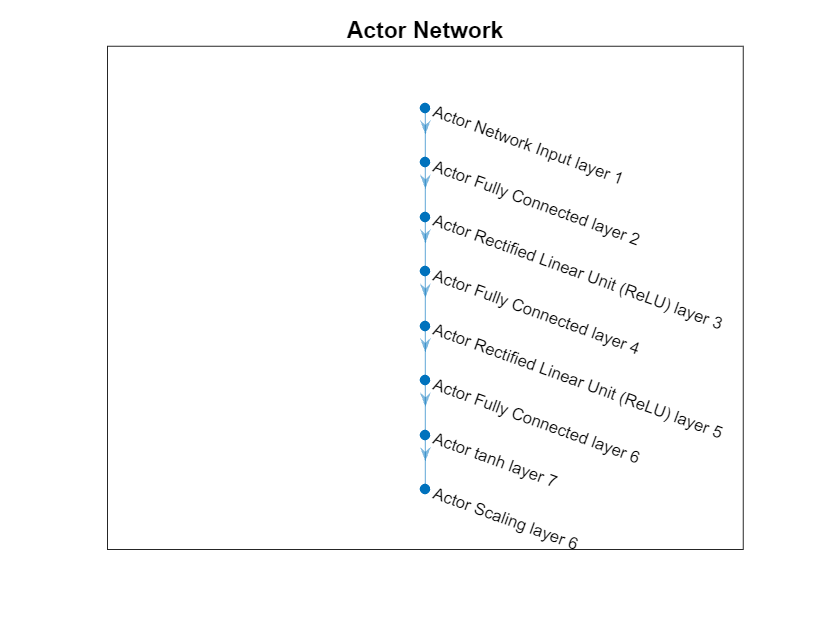

figure(5)
plot(actor_Network)
title("Actor Network")

Create the actor using `actorNet` and the observation and action specifications. For more information on continuous deterministic actors, see [rlContinuousDeterministicActor](https://www.mathworks.com/help/reinforcement-learning/ref/rl.function.rlcontinuousdeterministicactor.html)

[Create Policies and Value Functions](https://www.mathworks.com/help/reinforcement-learning/ug/create-policy-and-value-functions.html)

actor = rlContinuousDeterministicActor(actor_Network, Observation_Information,...
        Action_Information, ObservationInputNames = "Actor Network Input layer 1");

## Create the Agent

The information about different agents are given in [Reinforcement Learning Agents](https://www.mathworks.com/help/reinforcement-learning/ug/create-agents-for-reinforcement-learning.html)

Specify options for the critic and actor using [`rlOptimizerOptions`](docid:rl_ref#mw_18a712bb-b821-4dd9-a7ad-460ad7f2aa03)` and `DDPG agent options using [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c), include the training options for the actor and critic.

critic_Learning_Rate = 1e-03;
actor_Learning_Rate = 1e-04;
Discount_Factor = 0.99;
Batch_size = 128;
Buffer_length = 1e6;

critic_Options = rlOptimizerOptions(LearnRate = critic_Learning_Rate , GradientThreshold = 1);
actor_Options = rlOptimizerOptions(LearnRate = actor_Learning_Rate , GradientThreshold = 1);

agent_Options = rlDDPGAgentOptions(...
    SampleTime =              Ts,...
    CriticOptimizerOptions =  critic_Options,...
    ActorOptimizerOptions =   actor_Options,...
    ExperienceBufferLength =  Buffer_length,...
    DiscountFactor =          Discount_Factor,...
    MiniBatchSize =           Batch_size);

You can also modify the agent options using dot notation.

% initials actions are the initils parameters values
agent_Options.NoiseOptions.InitialAction = [PV_power_rating; Wind_power_rating; static_load_rating; TCL_load_rating; EV_load_rating]*0.25;

% Constant specifying how quickly the noise model output is attracted to the mean
agent_Options.NoiseOptions.MeanAttractionConstant = [0.3; 0.3; 0.3; 0.3; 0.3];

% varience
agent_Options.NoiseOptions.Variance =          [0.6; 0.6; 0.6; 0.6; 0.6];

% Variance Decay Rate
agent_Options.NoiseOptions.VarianceDecayRate = [1e-2; 1e-2; 1e-2; 1e-2; 1e-2];

% Standard Deviation Decay Rate 
agent_Options.NoiseOptions.StandardDeviationDecayRate = [0.9; 0.9; 0.9; 0.9; 0.9]; 

% Standard Deviation
agent_Options.NoiseOptions.StandardDeviation = [PV_power_rating; Wind_power_rating; static_load_rating; TCL_load_rating; EV_load_rating]*0.5/sqrt(Ts);

% Standard Deviation Min
agent_Options.NoiseOptions.StandardDeviationMin = [PV_power_rating; Wind_power_rating; static_load_rating; TCL_load_rating; EV_load_rating]*0.00001/sqrt(Ts)

agent_Options =   rlDDPGAgentOptions with properties:

                             SampleTime: 0.0500
                         DiscountFactor: 0.9900
                           NoiseOptions: [1×1 rl.option.OrnsteinUhlenbeckActionNoise]
                 ExperienceBufferLength: 1000000
                          MiniBatchSize: 128
                         SequenceLength: 1
                  ActorOptimizerOptions: [1×1 rl.option.rlOptimizerOptions]
                 CriticOptimizerOptions: [1×1 rl.option.rlOptimizerOptions]
                    NumStepsToLookAhead: 1
                     TargetSmoothFactor: 1.0000e-03
                  TargetUpdateFrequency: 1
            BatchDataRegularizerOptions: []
    ResetExperienceBufferBeforeTraining: 0
                             InfoToSave: [1×1 struct]


initial_options = rlAgentInitializationOptions(NumHiddenUnit=1024,UseRNN=true);

Alternatively, you can create the agent first, and then access its option object and modify the options using dot notation. Create the DDPG agent using the specified actor, critic, and agent options objects. For more information, see [`rlDDPGAgent`](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(actor , critic , agent_Options , initial_options)

agent =   rlDDPGAgent with properties:

        ExperienceBuffer: [1×1 rl.replay.rlReplayMemory]
            AgentOptions: [1×1 rl.option.rlDDPGAgentOptions]
    UseExplorationPolicy: 0
         ObservationInfo: [1×1 rl.util.rlNumericSpec]
              ActionInfo: [1×1 rl.util.rlNumericSpec]
              SampleTime: 0.0500


## Train Agent

To train the agent, first specify the training options. For this example, use the following options.

- Run training for at most 5000 episodes, with each episode lasting at most `ceil(Tf/Ts)` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than –740 over five consecutive episodes. At this point, the agent can quickly balance the pendulum in the upright position using minimal control effort.

- Save a copy of the agent for each episode where the cumulative reward is greater than –740.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

max_episodes = 5;
maxsteps = 1000;%ceil(Tf/Ts);
training_options = rlTrainingOptions(...
    MaxEpisodes =                 max_episodes,...
    MaxStepsPerEpisode =          maxsteps,...
    ScoreAveragingWindowLength =  5,...
    Verbose =                     false,...
    Plots =                      "training-progress",...
    StopTrainingCriteria =       "AverageReward",...
    StopTrainingValue =          50,...
    SaveAgentCriteria =          "EpisodeReward",...
    SaveAgentValue =             50);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false;
if doTraining
    % Train the agent.
    trainingStats = train(agent,environment,training_options);
end
save("agent1.mat","agent")

## Local Reset Function

function in = localResetFcn(in, varargin)

% Parameters Extraction
system_model =             varargin{1,1};                                     % data (vector): r rows, c points per signal
PV_power_rating =          varargin{1,2}; 
Wind_power_rating =        varargin{1,3}; 
battery_power_rating =     varargin{1,4}; 
nano_grid_controller_power_rating = varargin{1,5}; 
micro_grid_controller_power_rating = varargin{1,6}; 
static_load_rating =       varargin{1,7}; 
TCL_load_rating =          varargin{1,8}; 
EV_load_rating =           varargin{1,9}; 


% input state initial conditions
Wind_power_state = 0.5*Wind_power_rating;
battery_power_state = battery_power_rating;
nano_grid_controller_power_state = 0.1*nano_grid_controller_power_rating;
micro_grid_controller_power_state = 0.1*micro_grid_controller_power_rating;
static_load_state = 0.5*static_load_rating;
TCL_load_state = 0.5*TCL_load_rating;
EV_load_state = 0.5*EV_load_rating;


% input state initial randomization
% PV1 power state as initial condition
PV1_power_state = 100*randn;
PV1_power_forecast = 100*randn;
while PV1_power_state <= 0 || PV1_power_state >= PV_power_rating/1000
    PV1_power_state = 100*randn;
end
while PV1_power_forecast <= 0 || PV1_power_forecast >= PV_power_rating/1000
    PV1_power_forecast = 100*randn;
end
PV1_power_state = PV1_power_state*1000;
PV1_power_forecast = PV_power_rating;      % PV1_power_forecast*1000;
blk = system_model + "/PV1_100kW/PV1_power_state";
in = setBlockParameter(in, blk, Value = num2str(PV1_power_state));
blk = system_model + "/PV1_100kW/PV1_power_forecast";
in = setBlockParameter(in, blk, Value = num2str(PV1_power_forecast));


% Wind power state as initial condition
Wind_power_state = 100*randn;
Wind_power_forecast = 100*randn;
while Wind_power_state <= 0 || Wind_power_state >= Wind_power_rating/1000
    Wind_power_state = 100*randn;
end
while Wind_power_forecast <= 0 || Wind_power_forecast >= Wind_power_rating/1000
    Wind_power_forecast = 100*randn;
end
Wind_power_state = Wind_power_state*1000;
Wind_power_forecast = Wind_power_rating;      % Wind_power_forecast*1000;
blk = system_model + "/Wind_20kW/Wind_power_state";
in = setBlockParameter(in, blk, Value = num2str(Wind_power_state));
blk = system_model + "/Wind_20kW/Wind_power_forecast";
in = setBlockParameter(in, blk, Value = num2str(Wind_power_forecast));


% nano Grid Controller power state as initial condition
nano_grid_controller_power_state = 100*randn;
while nano_grid_controller_power_state <= 0 || nano_grid_controller_power_state >= nano_grid_controller_power_rating/1000
    nano_grid_controller_power_state = 100*randn;
end
nano_grid_controller_power_state = nano_grid_controller_power_state*1000;
blk = system_model + "/Nano_Grid_Controller2/nano_grid_controller_power_state";
in = setBlockParameter(in, blk, Value = num2str(nano_grid_controller_power_state));


% Micro Grid Controller power state as initial condition
micro_grid_controller_power_state = 100*randn;
while micro_grid_controller_power_state <= 0 || micro_grid_controller_power_state >= micro_grid_controller_power_rating/1000
    micro_grid_controller_power_state = 100*randn;
end
micro_grid_controller_power_state = micro_grid_controller_power_state*1000;
blk = system_model + "/Micro_Grid_Controller/micro_grid_controller_power_state";
in = setBlockParameter(in, blk, Value = num2str(micro_grid_controller_power_state));


% Static Load state as initial condition
static_load_state = 100*randn;
while static_load_state <= 0 || static_load_state >= static_load_rating/1000
    static_load_state = 100*randn;
end
static_load_state = static_load_state*1000;
blk = system_model + "/Load_100kW/Static_Load_demand";
in = setBlockParameter(in, blk, Value = num2str(static_load_state));


% TCL Load state as initial condition
TCL_load_state = 100*randn;
while TCL_load_state <= 0 || TCL_load_state >= TCL_load_rating/1000
    TCL_load_state = 100*randn;
end
TCL_load_state = TCL_load_state*1000;
blk = system_model + "/Load_100kW/TCL_Load_demand";
in = setBlockParameter(in, blk, Value = num2str(TCL_load_state));


% EV Load state as initial condition
EV_load_state = 100*randn;
while EV_load_state <= 0 || EV_load_state >= EV_load_rating/1000
    EV_load_state = 100*randn;
end
EV_load_state = EV_load_state*1000;
blk = system_model + "/Load_100kW/EV_Load_demand";
in = setBlockParameter(in, blk, Value = num2str(EV_load_state));

end